# Power-Split HEV for Speed Tracking

## Basic Simulation

This script runs the most basic simulation to check that the model is properly built.

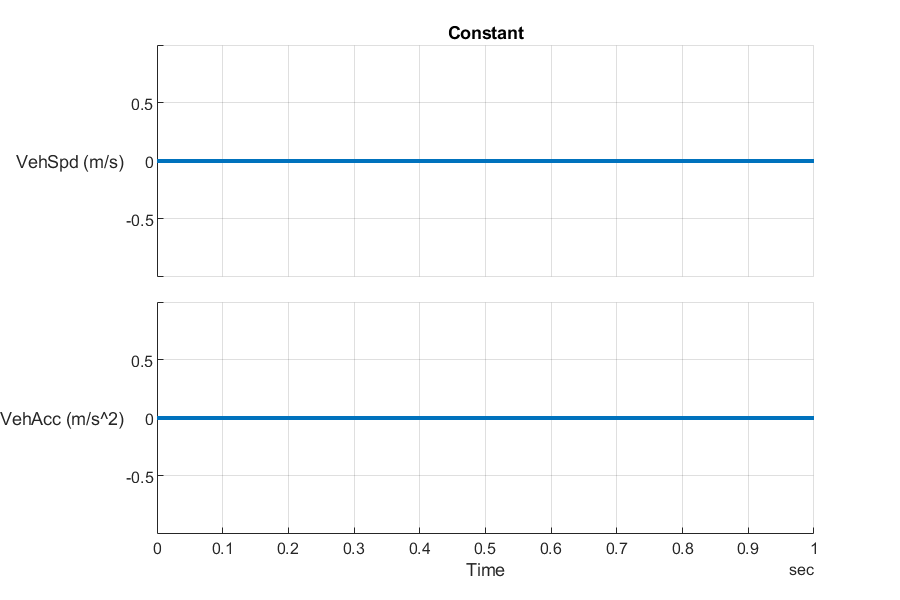

mdl = "PowerSplitHEV_system_model";

if not(bdIsLoaded(mdl))
  load_system(mdl);
end

% Use the speed tracking controller.
set_param(mdl+"/Controller & Environment", "ReferencedSubsystem", ...
  "PowerSplitHEV_SpeedTracking_refsub");

PowerSplitHEV_params

% Load external input signals - speed reference
drvPtnSigBuilder = DrivePattern_InputSignalBuilder;
drvPtnSigBuilder.Plot_tf = true;

inpData = Constant(drvPtnSigBuilder);

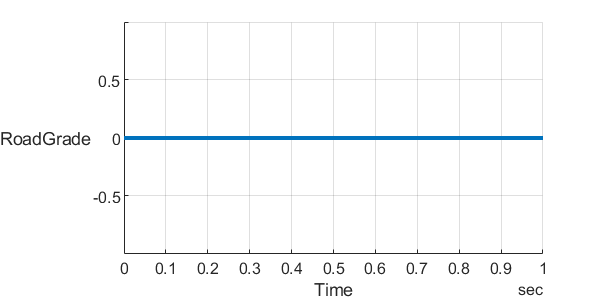


drivePatternFromWorkspace = inpData.Options.useFromWorkspace;

drivePattern_Signals = inpData.Signals;
drivePattern_Bus = inpData.Bus;

% Load external input signals - road grade
fig = figure;
[inputSignals, inputBus, opt2] = ...
  DriverAndEnvironment_road_grade_pattern( ...
    "InputPattern", "flat", ...
    "PlotParent", fig );


inputSignals_RoadGrade = inputSignals;
inputBus_RoadGrade = inputBus;

% Set simulation time.
t_end = max(inpData.Options.StopTime_s, opt2.t_end)

t_end = 1

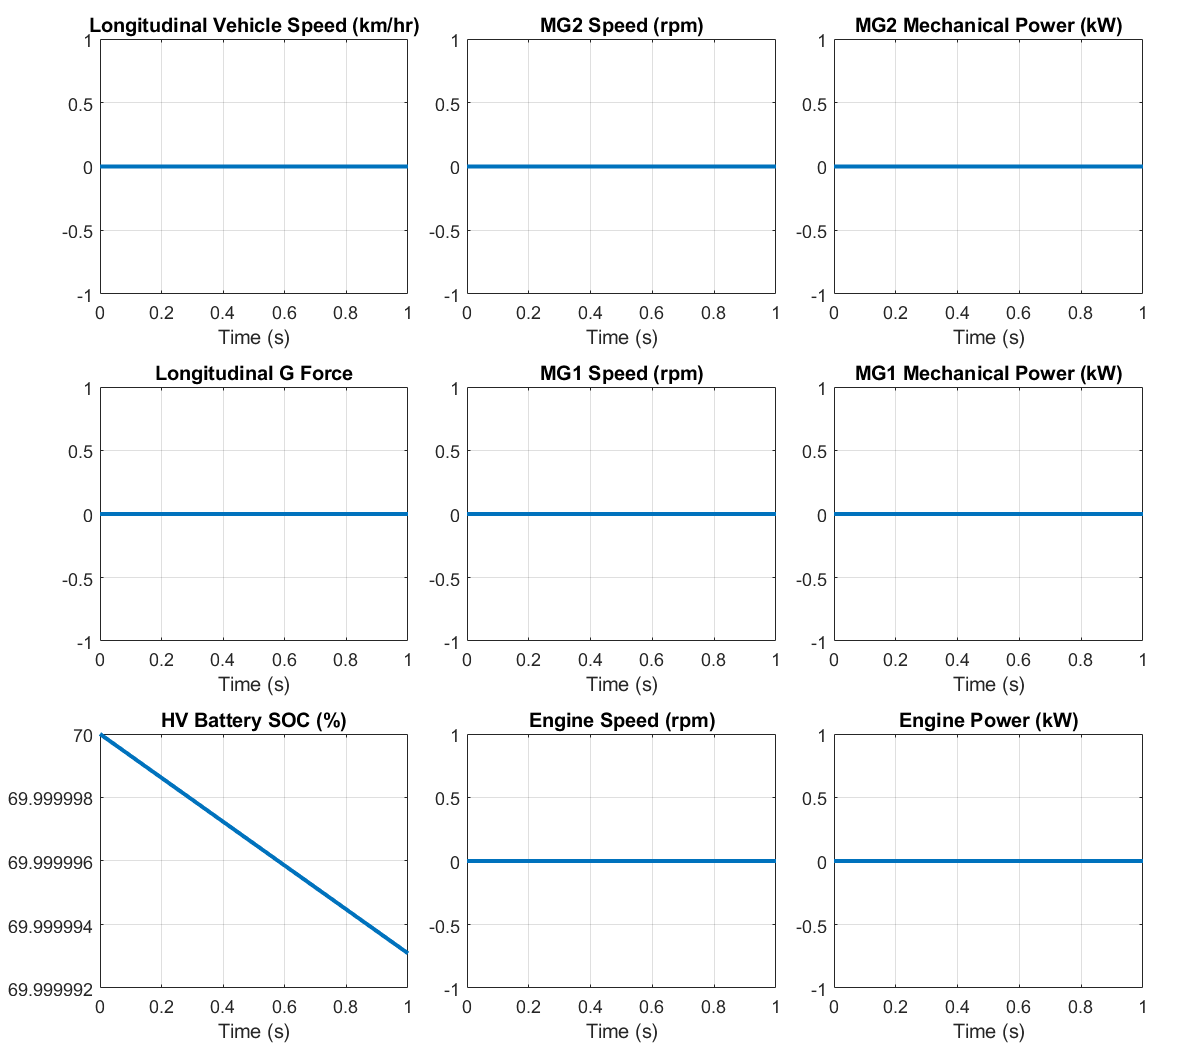

simIn = Simulink.SimulationInput(mdl);
simIn = setModelParameter(simIn, 'StopTime',num2str(t_end));

simOut = sim(simIn);

fig = figure;
PowerSplitHEV_plot_result_compact( ...
  "Dataset",simOut.logsout, "PlotParent",fig );

*Copyright 2021-2022 The MathWorks, Inc.*